# Robot PKM

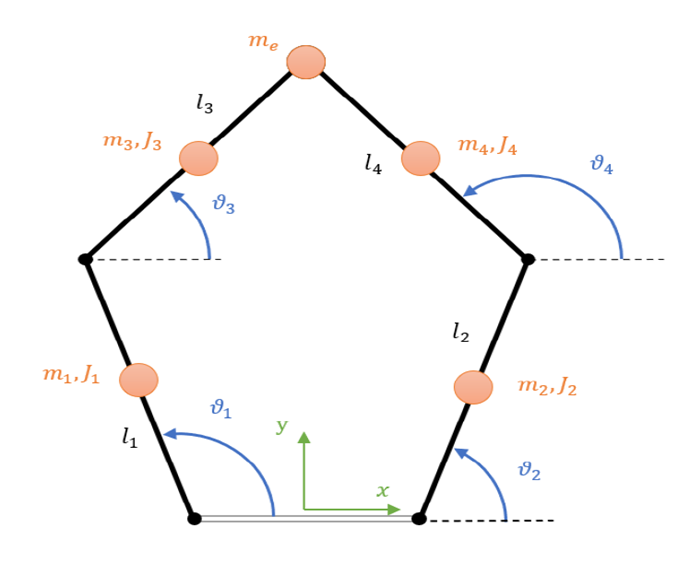

##   Definizione dati e informazioni utili manipolatore 

[PKM] = Define_Robot();

% Definizione parametri di test
theta1 = deg2rad(120); % Condizione iniziale posizione Theta1
theta2 = deg2rad(60); %  Condizione iniziale posizione Theta2
thetaV = deg2rad(720); % Angolo proprio della vite

theta1_p = 0; %  Condizione iniziale velocità theta1
theta2_p = 0; %  Condizione iniziale velocità tehta2
thetaV_p = 0; % Velocita thetav di prova

theta1_pp = 0; %  Condizione iniziale accelerazione theta1
theta2_pp = 0; %  Condizione iniziale accelarazione theta2
thetaV_pp = 0; % Accelerazione thetav di prova

## Legge di moto

Ldm_theta = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


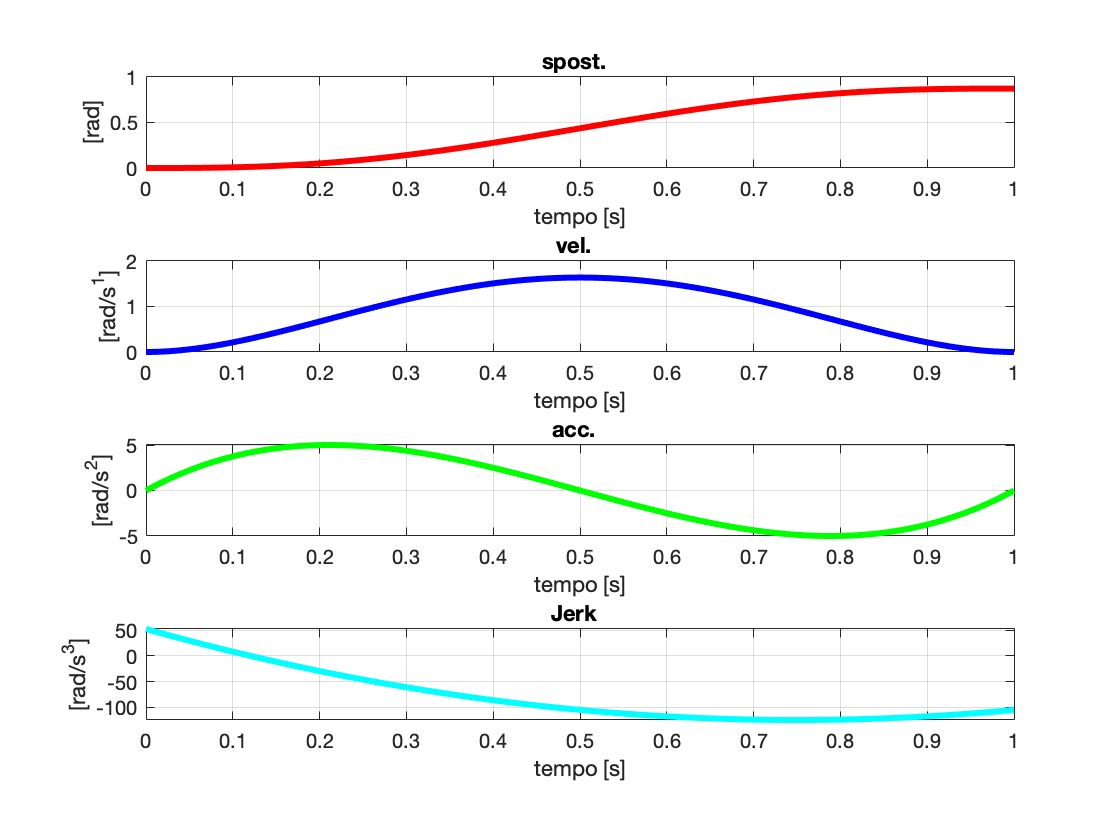

Ldm_theta1 = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


[Ldm_theta1] = Define_ldm(deg2rad(50), 'pol345') % Definisce una legge di moto data l'alzata in gradi per theta1

Ldm_theta = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


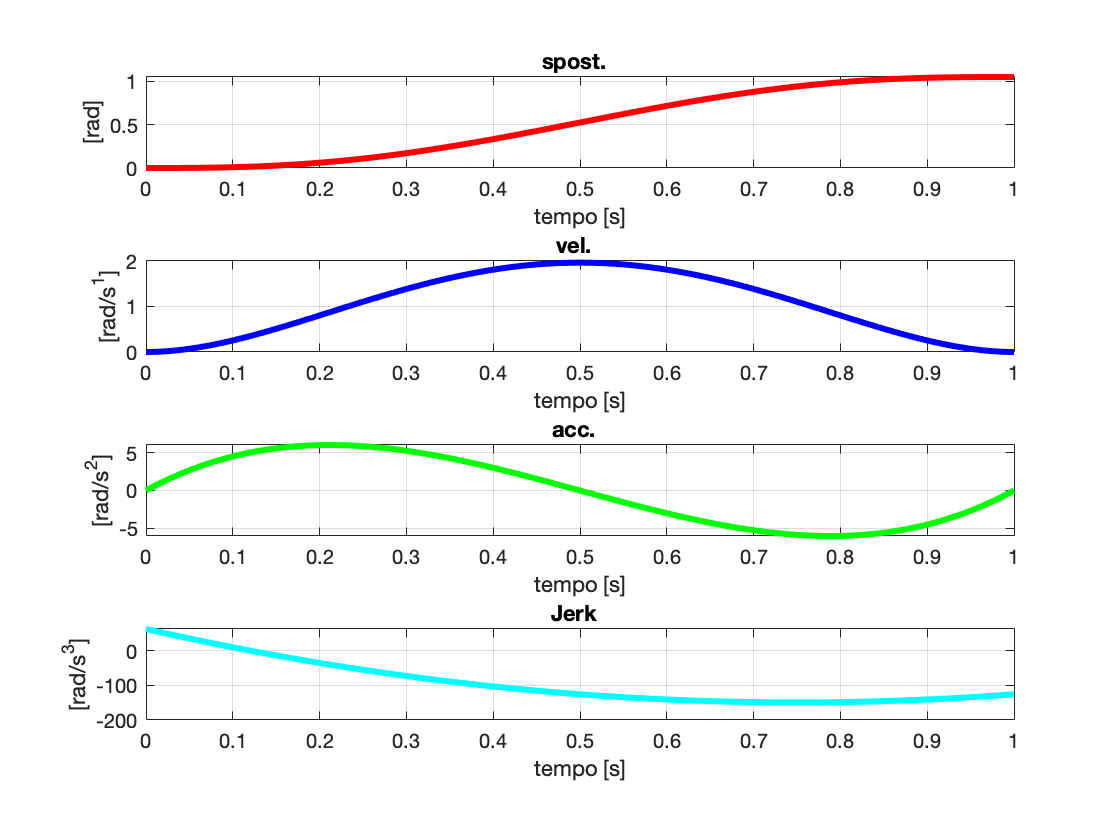

Ldm_theta2 = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


[Ldm_theta2] = Define_ldm(deg2rad(60), 'pol345') % Definisce una legge di moto data l'alzata in gradi per theta2

Ldm_theta = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


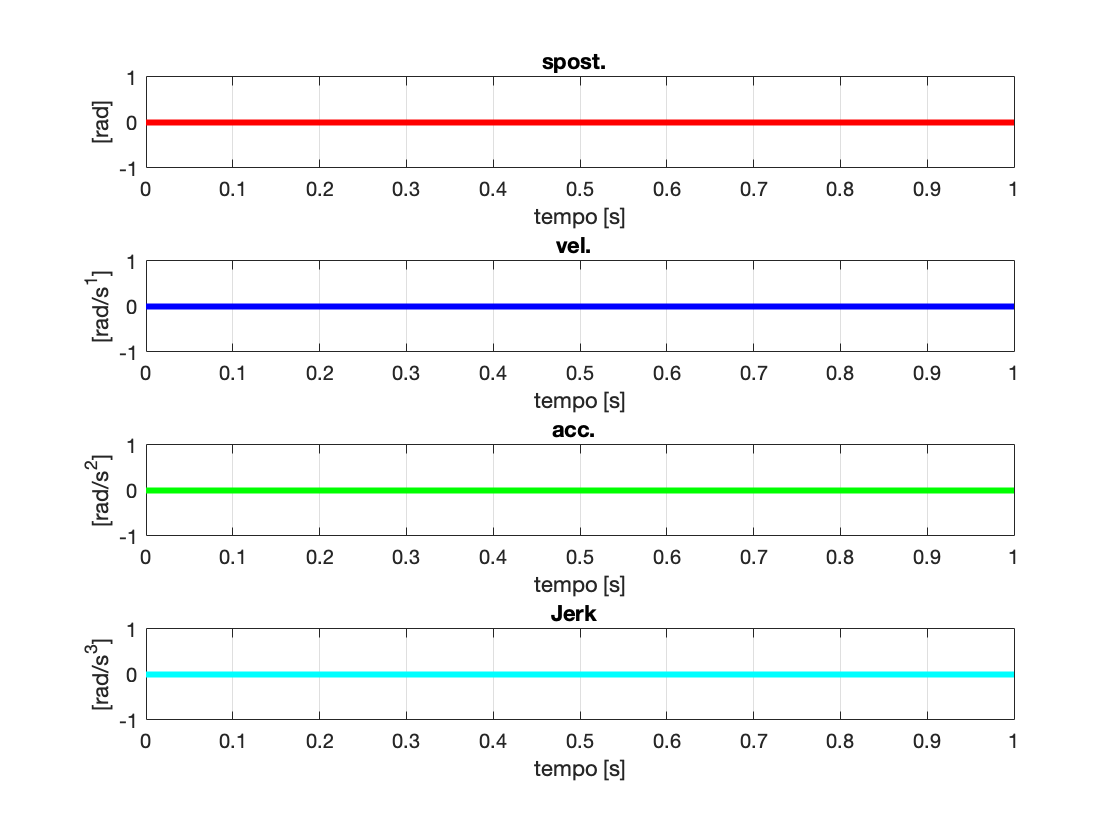

Ldm_thetav = struct with fields:
    vldm: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
    name: 'ldm composta PKM'
    time: [1×1 struct]
    disp: [1×1 struct]
    moto: [1×1 struct]


[Ldm_thetav] = Define_ldm(0, 'pol357') % Definisce una legge di moto per la vite


theta1ldm = theta1 + Ldm_theta1.moto.data{1,1}.v;
theta2ldm = theta2 + Ldm_theta2.moto.data{1,1}.v;
thetavldm = thetaV + Ldm_thetav.moto.data{1,1}.v;
PKM.ta = Ldm_theta1.vldm{1,1}.ta+Ldm_theta1.vldm{1,2}.ta+Ldm_theta1.vldm{1,3}.ta+Ldm_theta1.vldm{1,4}.ta;

Theta = [theta1ldm; theta2ldm; thetavldm]

Theta =     2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0945    2.0946    2.0946    2.0946    2.0946    2.0946    2.0947    2.0947    2.0947    2.0948    2.0948    2.0948    2.0948    2.0949    2.0949    2.0950    2.0950    2.0950    2.0951    2.0951    2.0952    2.0952    2.0953    2.0954
    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0473    1.0474    1.0474    1.0474    1.0474    1.0474    1.0475    1.0475    1.0475    1.0476    1.0476    1.0476    1.0477    1.0477    1.0477    1.0478    1.0478    1.0479    1.0479    1.0480    1.0480    1.0481    1.0482    1.0482    1.0483 

## Cinematica diretta

**Analisi di posizione**

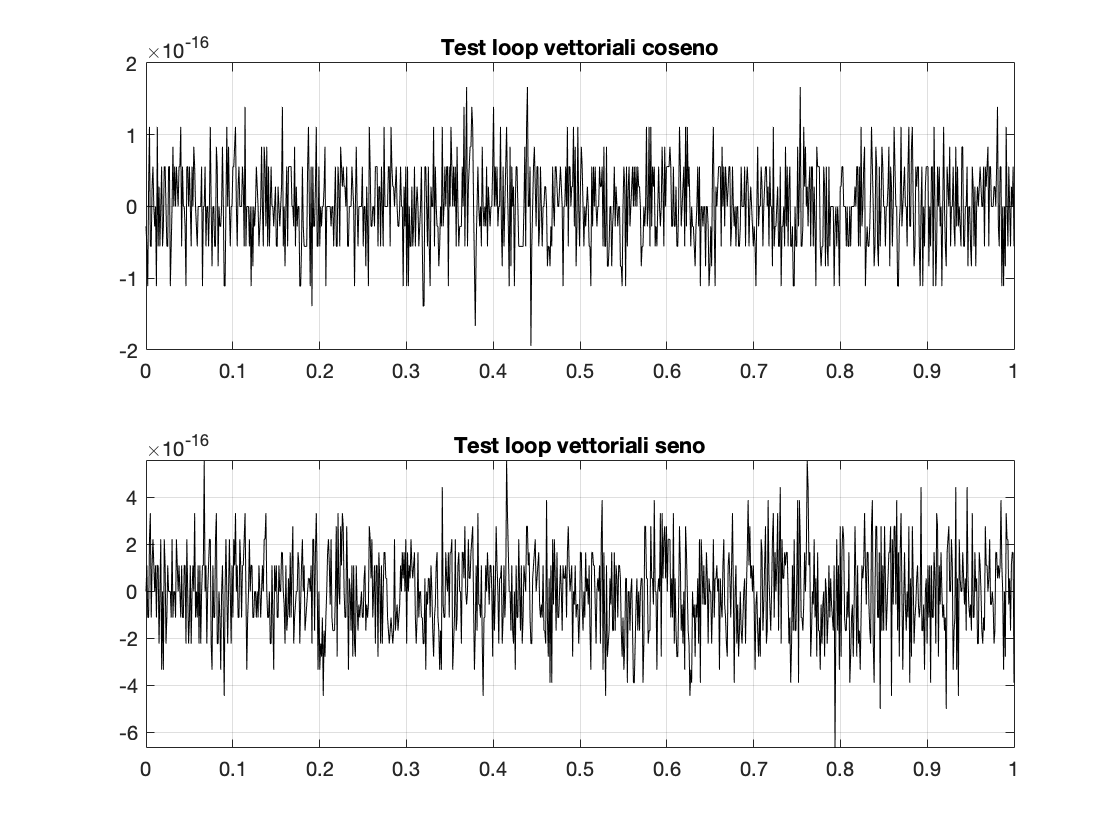

P =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0003
    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0.3441    0

theta3 =     0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5355    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5356    0.5357    0.5357    0.5357    0.5357    0.5357    0.5357    0.5358    0.5358    0.5358    0.5358    0.5359    0.5359    0.5359    0.5360    0.5360    0.5360    0.5361    0.5361    0.5361    0.5362    0.5362    0.5363    0.5363


theta4 =     2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6061    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6062    2.6063    2.6063    2.6063    2.6063    2.6063    2.6064    2.6064    2.6064    2.6064    2.6064    2.6065    2.6065    2.6065


E1 =    -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2150   -0.2151   -0.2151   -0.2151   -0.2151   -0.2151   -0.2151   -0.2151   -0.2151   -0.2151   -0.2151   -0.2151   -0.2151   -0.2151   -0.2152   -0.2152   -0.2152   -0.2152   -0.2152   -0.2152
    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    0.2164    

E2 =     0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2150    0.2149    0.2149    0.2149    0.2149    0.2149    0.2149    0.2149    0.2149    0.2149    0.2149    0.2149    0.2149    0.2149    0.2148    0.2148    0.2148    0.2148    0.2148    0.2148    0.2148    0.2148
    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2165    0.2166    0.2166    0.2166    0.2166    0.2166    0.2166    0.2166    0.2166    0.2166    0.2166    0.2166    0.2166    0.2166    0.2166    0.2166    0.2166    

[P, theta3, theta4, E1, E2] = Cinematica_Diretta_Posizione(PKM, theta1ldm, theta2ldm, thetavldm)

**Rappresentazione grafica**

%animation(PKM.link.d, PKM.link.l,theta1ldm,theta2ldm,theta3,theta4)

**Analisi di velocità**

theta1ldm_p = theta1_p + Ldm_theta1.moto.data{2,1}.v;
theta2ldm_p = theta2_p + Ldm_theta2.moto.data{2,1}.v;
thetavldm_p = thetaV_p + Ldm_thetav.moto.data{2,1}.v;

[P_p, J, P_pM] = Cinematica_Diretta_Velocita2(PKM, theta1ldm, theta2ldm, theta1ldm_p,theta2ldm_p,thetavldm_p,P)

P_p =          0   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0007   -0.0008   -0.0010   -0.0012   -0.0014   -0.0016   -0.0018   -0.0021   -0.0023   -0.0026   -0.0029   -0.0032   -0.0035   -0.0039   -0.0042   -0.0046   -0.0050   -0.0054   -0.0058   -0.0062   -0.0067   -0.0071   -0.0076   -0.0080   -0.0085   -0.0090   -0.0096   -0.0101   -0.0106   -0.0112   -0.0118   -0.0124   -0.0130   -0.0136   -0.0142   -0.0148   -0.0155   -0.0162   -0.0168   -0.0175   -0.0182
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027   

J =    -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453         0   -0.1453   -0.1453
   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0.2449         0   -0.2449    0

P_pM =    -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0007   -0.0009   -0.0011   -0.0013   -0.0015   -0.0017   -0.0020   -0.0022   -0.0025   -0.0028   -0.0031   -0.0034   -0.0037   -0.0041   -0.0044   -0.0048   -0.0052   -0.0056   -0.0060   -0.0064   -0.0069   -0.0073   -0.0078   -0.0083   -0.0088   -0.0093   -0.0098   -0.0104   -0.0109   -0.0115   -0.0121   -0.0127   -0.0133   -0.0139   -0.0145   -0.0152   -0.0158   -0.0165   -0.0172   -0.0179   -0.0186


Theta_p = [theta1ldm_p;theta2ldm_p;thetavldm_p]

Theta_p =          0    0.0000    0.0001    0.0002    0.0004    0.0006    0.0009    0.0013    0.0017    0.0021    0.0026    0.0031    0.0037    0.0043    0.0050    0.0057    0.0065    0.0073    0.0082    0.0091    0.0101    0.0111    0.0121    0.0132    0.0144    0.0156    0.0168    0.0181    0.0194    0.0208    0.0222    0.0237    0.0252    0.0267    0.0283    0.0299    0.0316    0.0333    0.0351    0.0368    0.0387    0.0406    0.0425    0.0444    0.0464    0.0484    0.0505    0.0526    0.0548    0.0570
         0    0.0000    0.0001    0.0003    0.0005    0.0008    0.0011    0.0015    0.0020    0.0025    0.0031    0.0037    0.0044    0.0052    0.0060    0.0069    0.0078    0.0088    0.0098    0.0109    0.0121    0.0133    0.0146    0.0159    0.0173    0.0187    0.0202    0.0217    0.0233    0.0250    0.0267    0.0284    0.0302    0.0321    0.0340    0.0359    0.0379    0.0400    0.0421    0.0442    0.0464    0.0487    0.0510    0.0533    0.0557    0.0581    0.0606    0.0631    0.065

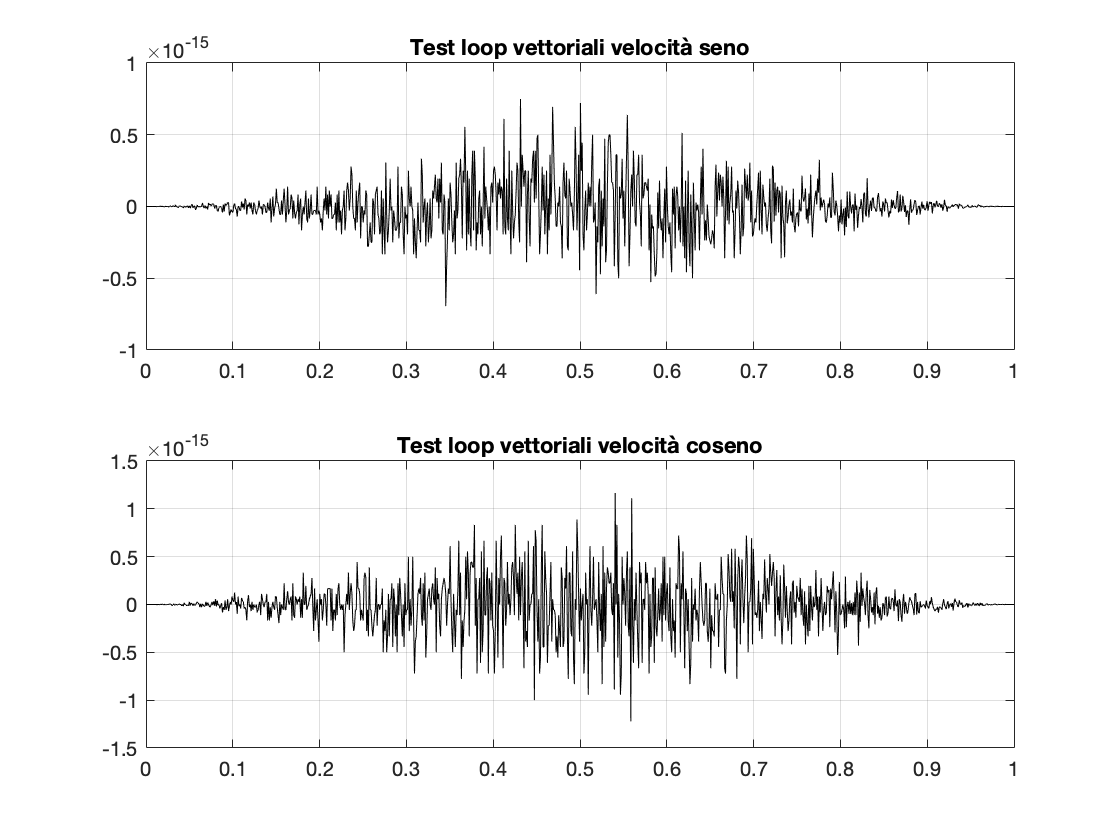

theta3_p =          0    0.0000    0.0001    0.0002    0.0003    0.0005    0.0008    0.0010    0.0013    0.0017    0.0021    0.0025    0.0030    0.0035    0.0040    0.0046    0.0053    0.0059    0.0066    0.0074    0.0082    0.0090    0.0098    0.0107    0.0116    0.0126    0.0136    0.0147    0.0157    0.0168    0.0180    0.0192    0.0204    0.0216    0.0229    0.0242    0.0256    0.0270    0.0284    0.0298    0.0313    0.0328    0.0344    0.0360    0.0376    0.0392    0.0409    0.0426    0.0443    0.0461


theta4_p =          0    0.0000    0.0000    0.0001    0.0002    0.0003    0.0004    0.0006    0.0008    0.0010    0.0012    0.0015    0.0017    0.0020    0.0023    0.0027    0.0031    0.0034    0.0039    0.0043    0.0047    0.0052    0.0057    0.0062    0.0068    0.0073    0.0079    0.0085    0.0091    0.0098    0.0104    0.0111    0.0118    0.0125    0.0133    0.0141    0.0148    0.0156    0.0165    0.0173    0.0182    0.0190    0.0199    0.0209    0.0218    0.0227    0.0237    0.0247    0.0257    0.0267


J34 =    -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5578    1.1392   -0.5578    1.1392   -0.5578    1.1392   -0.5578    1.1392   -0.5578    1.1392   -0.5578    1.1392   -0.5578    1.1392   -0.5578    1.1392   -0.5578    1.1392   -0.5578    1.1392   -0.5578    1.1392   -0.5578    1.1392   -0.5578    1.1392
    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1393   -0.5579    1.1392   -0.5579    1.1392   -0.5579    1.1392   -0.5579    1.1392   -0.5579    1.1392   -0.5579    1.1392   -0.5579    1.1392   -0.5579    1.1392   -0.5579    1.1392   -0.5579    1.1392   -0.5579    1.1392   -0.5579    1.1392   -0.5579    1.1392   

[theta3_p,theta4_p,J34] = Theta34p(PKM,theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p)

**Analisi di accelerazione**

theta1ldm_pp = theta1_p + Ldm_theta1.moto.data{3,1}.v;
theta2ldm_pp = theta2_p + Ldm_theta2.moto.data{3,1}.v;
thetavldm_pp = thetaV_p + Ldm_thetav.moto.data{3,1}.v;

Theta_pp = [theta1ldm_pp;theta2ldm_pp;thetavldm_pp]

Theta_pp =          0    0.0523    0.1042    0.1558    0.2071    0.2581    0.3088    0.3592    0.4093    0.4590    0.5085    0.5576    0.6065    0.6550    0.7032    0.7511    0.7987    0.8460    0.8930    0.9397    0.9861    1.0322    1.0780    1.1235    1.1687    1.2136    1.2582    1.3025    1.3465    1.3901    1.4335    1.4767    1.5195    1.5620    1.6042    1.6461    1.6878    1.7291    1.7702    1.8109    1.8514    1.8916    1.9315    1.9711    2.0104    2.0494    2.0881    2.1266    2.1648    2.2027
         0    0.0627    0.1250    0.1870    0.2486    0.3098    0.3706    0.4311    0.4911    0.5508    0.6102    0.6692    0.7278    0.7860    0.8439    0.9014    0.9585    1.0152    1.0716    1.1277    1.1834    1.2387    1.2936    1.3482    1.4024    1.4563    1.5098    1.5630    1.6157    1.6682    1.7203    1.7720    1.8234    1.8744    1.9250    1.9754    2.0253    2.0749    2.1242    2.1731    2.2217    2.2699    2.3177    2.3653    2.4124    2.4593    2.5058    2.5519    2.59

[P_pp] = Cinematica_Diretta_Accelerazione2(PKM,Theta, Theta_p, Theta_pp, P, P_p)

P_pp =          0   -0.0167   -0.0333   -0.0498   -0.0662   -0.0825   -0.0987   -0.1149   -0.1309   -0.1468   -0.1626   -0.1783   -0.1939   -0.2094   -0.2249   -0.2402   -0.2554   -0.2705   -0.2856   -0.3005   -0.3153   -0.3301   -0.3447   -0.3593   -0.3737   -0.3881   -0.4023   -0.4165   -0.4306   -0.4445   -0.4584   -0.4722   -0.4859   -0.4995   -0.5130   -0.5264   -0.5398   -0.5530   -0.5661   -0.5792   -0.5921   -0.6050   -0.6178   -0.6304   -0.6430   -0.6555   -0.6679   -0.6803   -0.6925   -0.7046
         0    0.0026    0.0051    0.0076    0.0101    0.0126    0.0151    0.0176    0.0200    0.0225    0.0249    0.0273    0.0297    0.0321    0.0344    0.0368    0.0391    0.0414    0.0437    0.0460    0.0483    0.0505    0.0528    0.0550    0.0572    0.0594    0.0615    0.0637    0.0658    0.0679    0.0700    0.0721    0.0742    0.0763    0.0783    0.0803    0.0823    0.0843    0.0863    0.0882    0.0901    0.0921    0.0940    0.0958    0.0977    0.0995    0.1014    0.1032    0.1050  

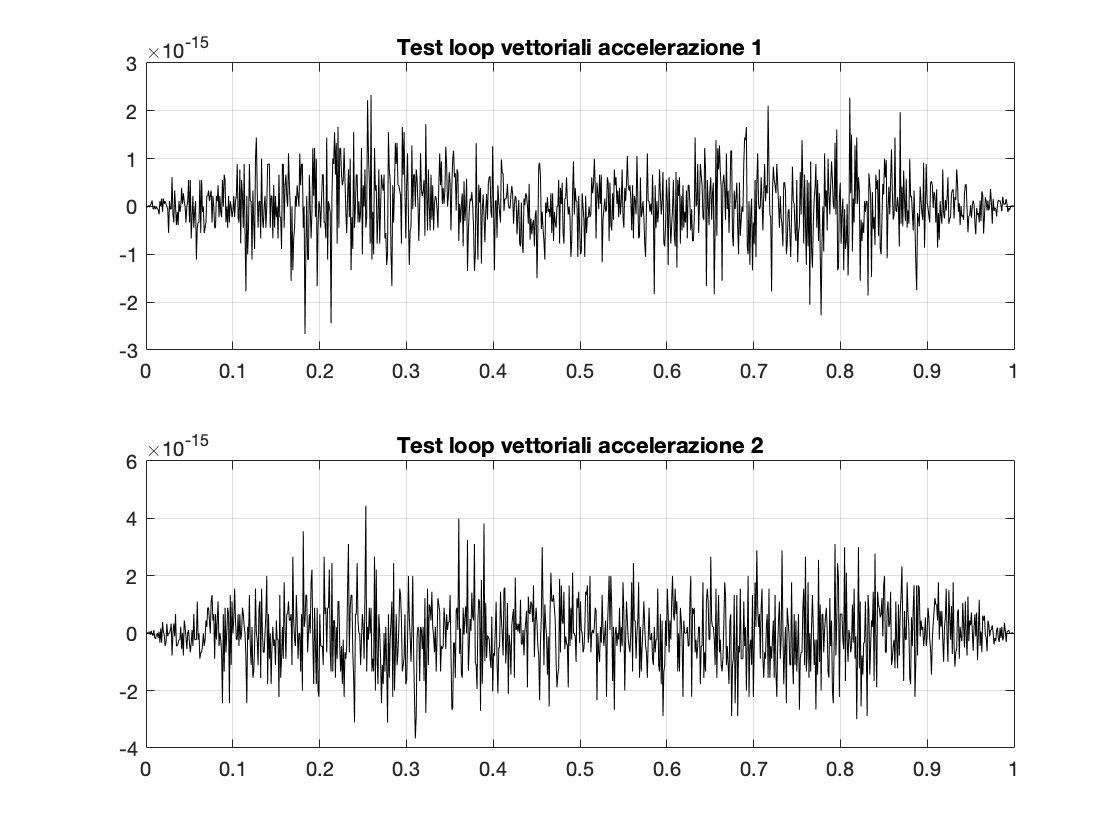

theta3_pp =          0    0.0423    0.0843    0.1261    0.1676    0.2089    0.2499    0.2907    0.3312    0.3715    0.4115    0.4513    0.4908    0.5301    0.5691    0.6079    0.6464    0.6847    0.7227    0.7605    0.7981    0.8354    0.8725    0.9093    0.9459    0.9822    1.0183    1.0542    1.0898    1.1252    1.1604    1.1953    1.2300    1.2645    1.2987    1.3327    1.3664    1.3999    1.4332    1.4663    1.4991    1.5317    1.5641    1.5963    1.6282    1.6599    1.6914    1.7226    1.7536    1.7844


theta4_pp =          0    0.0246    0.0490    0.0732    0.0973    0.1213    0.1451    0.1688    0.1923    0.2157    0.2389    0.2620    0.2849    0.3077    0.3304    0.3529    0.3752    0.3974    0.4195    0.4414    0.4632    0.4848    0.5063    0.5277    0.5489    0.5699    0.5909    0.6116    0.6323    0.6527    0.6731    0.6933    0.7133    0.7332    0.7530    0.7726    0.7920    0.8114    0.8305    0.8496    0.8685    0.8872    0.9058    0.9243    0.9426    0.9607    0.9787    0.9966    1.0143    1.0319


J34p =          0         0    0.0000   -0.0000    0.0001   -0.0000    0.0001   -0.0001    0.0003   -0.0001    0.0004   -0.0001    0.0006   -0.0002    0.0008   -0.0003    0.0010   -0.0004    0.0013   -0.0005    0.0016   -0.0006    0.0020   -0.0007    0.0023   -0.0008    0.0027   -0.0010    0.0031   -0.0011    0.0036   -0.0013    0.0041   -0.0014    0.0046   -0.0016    0.0052   -0.0018    0.0057   -0.0020    0.0063   -0.0022    0.0070   -0.0025    0.0077   -0.0027    0.0083   -0.0029    0.0091   -0.0032
         0         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0003   -0.0005   -0.0004   -0.0006   -0.0005   -0.0007   -0.0006   -0.0009   -0.0008   -0.0011   -0.0009   -0.0012   -0.0010   -0.0014   -0.0012   -0.0016   -0.0014   -0.0019   -0.0015   -0.0021   -0.0017   -0.0023   -0.0019   -0.0026   -0.0021   -0.0029   -0.0023   -0.0032   -0.0025   -0.0035   -0.0028   -0.0038   -0.0030  

[theta3_pp,theta4_pp,J34p] = Theta34pp(theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p,...
    theta3_p,theta4_p,theta1ldm_pp, theta2ldm_pp,J34)


[C1_p, C2_p, C1_pp, C2_pp, E1_p, E1_pp, J1, J1p, J2, J2p, J3, J3p, J4, J4p, JE, JEp,P_p34, P_pp34] = Jacobiani(PKM, Theta, Theta_p, theta3, theta4, theta3_p, theta4_p, J34, J34p, P_pp, Theta_pp)

C1_p =          0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0016   -0.0017   -0.0018   -0.0020   -0.0021   -0.0023   -0.0024   -0.0026   -0.0027   -0.0029   -0.0031   -0.0032   -0.0034   -0.0036   -0.0038   -0.0040   -0.0042   -0.0044   -0.0046   -0.0048   -0.0050   -0.0052   -0.0055   -0.0057   -0.0059   -0.0062
         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0008   -0.0008   -0.0009   -0.0010   -0.0011   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0016   -0.0017   -0.0018   -0.0019   -0.0020   -0.0021   -0.0022   -0.0023   -0.0024   -0.0025   -0.0027   -0.0028   -0.0029   -0.0030   -0.0032   -0.0033   -0.0034  

C2_p =          0   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0005   -0.0006   -0.0006   -0.0007   -0.0008   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0016   -0.0017   -0.0019   -0.0020   -0.0022   -0.0024   -0.0025   -0.0027   -0.0029   -0.0031   -0.0033   -0.0035   -0.0037   -0.0039   -0.0041   -0.0043   -0.0046   -0.0048   -0.0050   -0.0053   -0.0055   -0.0058   -0.0060   -0.0063   -0.0066   -0.0068   -0.0071   -0.0074
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0024    0.0025    0.0026    0.0028    0.0029    0.0030    0.0032    0.0033    0.0035    0.0036    0.0038    0.0039    0.0041  

C1_pp =          0   -0.0057   -0.0113   -0.0169   -0.0224   -0.0279   -0.0334   -0.0389   -0.0443   -0.0497   -0.0550   -0.0604   -0.0657   -0.0709   -0.0761   -0.0813   -0.0865   -0.0916   -0.0967   -0.1017   -0.1067   -0.1117   -0.1167   -0.1216   -0.1265   -0.1313   -0.1362   -0.1410   -0.1457   -0.1504   -0.1551   -0.1598   -0.1644   -0.1690   -0.1736   -0.1781   -0.1826   -0.1871   -0.1915   -0.1959   -0.2003   -0.2046   -0.2089   -0.2132   -0.2174   -0.2216   -0.2258   -0.2299   -0.2340   -0.2381
         0   -0.0033   -0.0065   -0.0097   -0.0129   -0.0161   -0.0193   -0.0225   -0.0256   -0.0287   -0.0318   -0.0349   -0.0379   -0.0409   -0.0440   -0.0470   -0.0499   -0.0529   -0.0558   -0.0587   -0.0617   -0.0645   -0.0674   -0.0703   -0.0731   -0.0759   -0.0787   -0.0815   -0.0842   -0.0870   -0.0897   -0.0924   -0.0951   -0.0978   -0.1004   -0.1030   -0.1057   -0.1083   -0.1109   -0.1134   -0.1160   -0.1185   -0.1210   -0.1235   -0.1260   -0.1285   -0.1310   -0.1334   -0.1358 

C2_pp =          0   -0.0068   -0.0135   -0.0202   -0.0269   -0.0335   -0.0401   -0.0467   -0.0532   -0.0596   -0.0661   -0.0724   -0.0788   -0.0851   -0.0914   -0.0976   -0.1038   -0.1099   -0.1160   -0.1221   -0.1281   -0.1341   -0.1401   -0.1460   -0.1518   -0.1577   -0.1635   -0.1692   -0.1750   -0.1807   -0.1863   -0.1919   -0.1975   -0.2030   -0.2085   -0.2140   -0.2194   -0.2248   -0.2301   -0.2354   -0.2407   -0.2460   -0.2512   -0.2563   -0.2615   -0.2666   -0.2716   -0.2767   -0.2817   -0.2866
         0    0.0039    0.0078    0.0117    0.0155    0.0194    0.0232    0.0269    0.0307    0.0344    0.0381    0.0418    0.0455    0.0491    0.0527    0.0563    0.0599    0.0634    0.0670    0.0705    0.0739    0.0774    0.0808    0.0842    0.0876    0.0910    0.0943    0.0976    0.1009    0.1041    0.1074    0.1106    0.1138    0.1170    0.1201    0.1232    0.1263    0.1294    0.1324    0.1355    0.1385    0.1414    0.1444    0.1473    0.1502    0.1531    0.1560    0.1588    0.1616 

E1_p =          0   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0007   -0.0008   -0.0009   -0.0011   -0.0012   -0.0014   -0.0016   -0.0018   -0.0020   -0.0022   -0.0024   -0.0026   -0.0029   -0.0031   -0.0034   -0.0036   -0.0039   -0.0042   -0.0045   -0.0048   -0.0051   -0.0054   -0.0058   -0.0061   -0.0065   -0.0068   -0.0072   -0.0076   -0.0080   -0.0084   -0.0088   -0.0092   -0.0096   -0.0100   -0.0105   -0.0109   -0.0114   -0.0119   -0.0123
         0   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0008   -0.0009   -0.0010   -0.0011   -0.0013   -0.0014   -0.0015   -0.0017   -0.0018   -0.0019   -0.0021   -0.0023   -0.0024   -0.0026   -0.0028   -0.0030   -0.0031   -0.0033   -0.0035   -0.0037   -0.0040   -0.0042   -0.0044   -0.0046   -0.0048   -0.0051   -0.0053   -0.0056   -0.0058   -0.0061   -0.0063   -0.0066   -0.0069  

E1_pp =          0   -0.0113   -0.0226   -0.0337   -0.0448   -0.0559   -0.0669   -0.0778   -0.0886   -0.0994   -0.1101   -0.1207   -0.1313   -0.1418   -0.1522   -0.1626   -0.1729   -0.1832   -0.1933   -0.2034   -0.2135   -0.2235   -0.2334   -0.2432   -0.2530   -0.2627   -0.2723   -0.2819   -0.2914   -0.3009   -0.3103   -0.3196   -0.3288   -0.3380   -0.3472   -0.3562   -0.3652   -0.3741   -0.3830   -0.3918   -0.4005   -0.4092   -0.4178   -0.4263   -0.4348   -0.4432   -0.4516   -0.4599   -0.4681   -0.4762
         0   -0.0065   -0.0130   -0.0195   -0.0259   -0.0323   -0.0386   -0.0449   -0.0512   -0.0574   -0.0636   -0.0697   -0.0758   -0.0819   -0.0879   -0.0939   -0.0999   -0.1058   -0.1117   -0.1175   -0.1233   -0.1291   -0.1348   -0.1405   -0.1462   -0.1518   -0.1574   -0.1629   -0.1684   -0.1739   -0.1794   -0.1848   -0.1902   -0.1955   -0.2008   -0.2061   -0.2113   -0.2165   -0.2217   -0.2268   -0.2320   -0.2370   -0.2421   -0.2471   -0.2521   -0.2570   -0.2619   -0.2668   -0.2717 

J1 =    -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1082         0   -0.1082         0   -0.1082         0   -0.1082         0   -0.1082         0   -0.1082         0
   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625         0   -0.0625    

J1p =          0         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0000         0    0.0001         0    0.0001         0    0.0001         0    0.0001         0    0.0002         0    0.0002         0    0.0002         0    0.0003         0    0.0003         0    0.0004         0    0.0004         0    0.0005         0    0.0005         0    0.0006         0    0.0006         0    0.0007         0    0.0008         0    0.0008         0    0.0009         0
         0         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0002         0   -0.0002         0   -0.0003         0   -0.0003         0   -0.0004         0   -0.0005         0   -0.0005         0   -0.0006         0   -0.0007         0   -0.0008         0   -0.0009         0   -0.0010         0   -0.0011         0   -0.0012         0   -0.0013         0   -0.0014         0   -0.0016   

J2 =          0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083         0   -0.1083
         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    0.0625         0    

J2p =          0         0         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0002         0   -0.0002         0   -0.0002         0   -0.0003         0   -0.0003         0   -0.0004         0   -0.0004         0   -0.0005         0   -0.0005         0   -0.0006         0   -0.0007         0   -0.0008         0   -0.0008         0   -0.0009         0   -0.0010         0   -0.0011
         0         0         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0001         0   -0.0001         0   -0.0001         0   -0.0002         0   -0.0002         0   -0.0003         0   -0.0003         0   -0.0004         0   -0.0005         0   -0.0006         0   -0.0006         0   -0.0007         0   -0.0008         0   -0.0010         0   -0.0011         0   -0.0012         0   -0.0013         0   -0.0014         0   -0.0016         0   -0.0017         0   

J3 =    -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727
   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    0.1225   -0.1850    

J3p =          0         0    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0000    0.0001   -0.0001    0.0001   -0.0001    0.0002   -0.0001    0.0002   -0.0001    0.0003   -0.0002    0.0003   -0.0002    0.0004   -0.0003    0.0005   -0.0003    0.0006   -0.0004    0.0007   -0.0004    0.0008   -0.0005    0.0009   -0.0006    0.0010   -0.0006    0.0011   -0.0007    0.0012   -0.0008    0.0013   -0.0009    0.0015   -0.0009    0.0016   -0.0010    0.0018   -0.0011    0.0019   -0.0012
         0         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0003   -0.0002   -0.0003   -0.0002   -0.0004   -0.0003   -0.0004   -0.0003   -0.0005   -0.0004   -0.0006   -0.0004   -0.0007   -0.0005   -0.0008   -0.0005   -0.0009   -0.0006   -0.0010   -0.0007   -0.0011   -0.0008   -0.0012   -0.0008   -0.0013   -0.0009   -0.0015   -0.0010   -0.0016   -0.0011   -0.0017   

J4 =    -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809   -0.0727   -0.1809
   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1850   -0.1225    0.1849   -0.1225    

J4p =          0         0    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0001    0.0000   -0.0001    0.0001   -0.0001    0.0001   -0.0002    0.0001   -0.0003    0.0001   -0.0003    0.0002   -0.0004    0.0002   -0.0005    0.0003   -0.0006    0.0003   -0.0007    0.0004   -0.0008    0.0004   -0.0009    0.0005   -0.0010    0.0005   -0.0012    0.0006   -0.0013    0.0006   -0.0015    0.0007   -0.0016    0.0008   -0.0018    0.0009   -0.0019    0.0009   -0.0021    0.0010   -0.0023
         0         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0001   -0.0000   -0.0002   -0.0000   -0.0003   -0.0000   -0.0004   -0.0000   -0.0004   -0.0000   -0.0005   -0.0000   -0.0007   -0.0000   -0.0008   -0.0001   -0.0009   -0.0001   -0.0011   -0.0001   -0.0012   -0.0001   -0.0014   -0.0001   -0.0016   -0.0001   -0.0017   -0.0001   -0.0019   -0.0001   -0.0021   -0.0001   -0.0024   -0.0001   -0.0026   -0.0002   -0.0028   -0.0002   

JE =    -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1453   -0.1454   -0.1453   -0.1454   -0.1453   -0.1454   -0.1453   -0.1454   -0.1453   -0.1454
   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    0.2449   -0.2449    

JEp =          0         0    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0001    0.0001   -0.0001    0.0001   -0.0002    0.0002   -0.0002    0.0002   -0.0003    0.0003   -0.0004    0.0004   -0.0004    0.0004   -0.0005    0.0005   -0.0006    0.0006   -0.0007    0.0007   -0.0008    0.0008   -0.0010    0.0009   -0.0011    0.0010   -0.0012    0.0012   -0.0014    0.0013   -0.0015    0.0014   -0.0017    0.0016   -0.0019    0.0017   -0.0021    0.0019   -0.0023    0.0020   -0.0024
         0         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0001   -0.0000   -0.0002   -0.0000   -0.0002   -0.0000   -0.0003   -0.0000   -0.0003   -0.0001   -0.0004   -0.0001   -0.0005   -0.0001   -0.0006   -0.0001   -0.0007   -0.0001   -0.0008   -0.0001   -0.0009   -0.0002   -0.0011   -0.0002   -0.0012   -0.0002   -0.0014   -0.0002   -0.0015   -0.0002   -0.0017   -0.0003   -0.0018   -0.0003   -0.0020   -0.0003   -0.0022   -0.0003   

P_p34 =          0   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0007   -0.0008   -0.0010   -0.0012   -0.0014   -0.0016   -0.0018   -0.0021   -0.0023   -0.0026   -0.0029   -0.0032   -0.0035   -0.0039   -0.0042   -0.0046   -0.0050   -0.0054   -0.0058   -0.0062   -0.0067   -0.0071   -0.0076   -0.0080   -0.0085   -0.0090   -0.0096   -0.0101   -0.0106   -0.0112   -0.0118   -0.0124   -0.0130   -0.0136   -0.0142   -0.0148   -0.0155   -0.0162   -0.0168   -0.0175   -0.0182
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027 

P_pp34 =          0   -0.0167   -0.0333   -0.0498   -0.0662   -0.0825   -0.0987   -0.1149   -0.1309   -0.1468   -0.1626   -0.1783   -0.1939   -0.2094   -0.2249   -0.2402   -0.2554   -0.2705   -0.2856   -0.3005   -0.3153   -0.3301   -0.3447   -0.3593   -0.3737   -0.3881   -0.4023   -0.4165   -0.4306   -0.4445   -0.4584   -0.4722   -0.4859   -0.4995   -0.5130   -0.5264   -0.5398   -0.5530   -0.5661   -0.5792   -0.5921   -0.6050   -0.6178   -0.6304   -0.6430   -0.6555   -0.6679   -0.6803   -0.6925   -0.7046
         0    0.0026    0.0051    0.0076    0.0101    0.0126    0.0151    0.0176    0.0200    0.0225    0.0249    0.0273    0.0297    0.0321    0.0344    0.0368    0.0391    0.0414    0.0437    0.0460    0.0483    0.0505    0.0528    0.0550    0.0572    0.0594    0.0615    0.0637    0.0658    0.0679    0.0700    0.0721    0.0742    0.0763    0.0783    0.0803    0.0823    0.0843    0.0863    0.0882    0.0901    0.0921    0.0940    0.0958    0.0977    0.0995    0.1014    0.1032    0.1050

**Confronto cinematica analitica e derivata numerica**

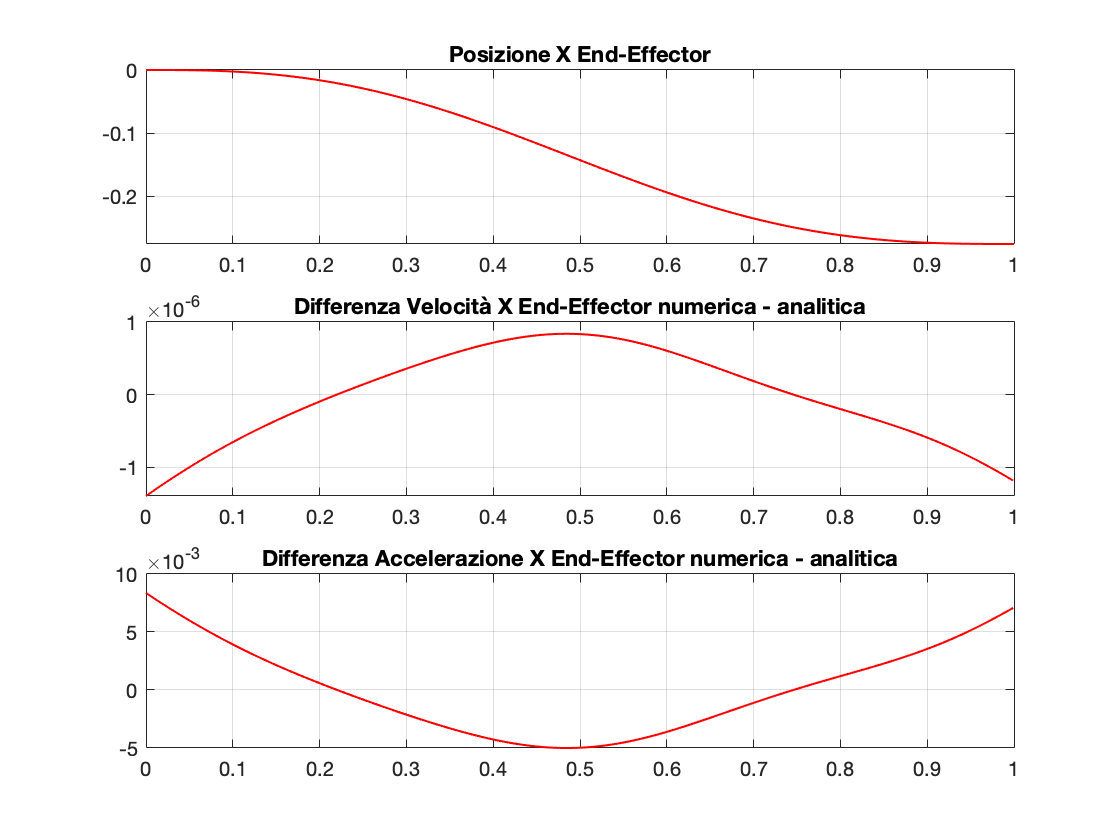

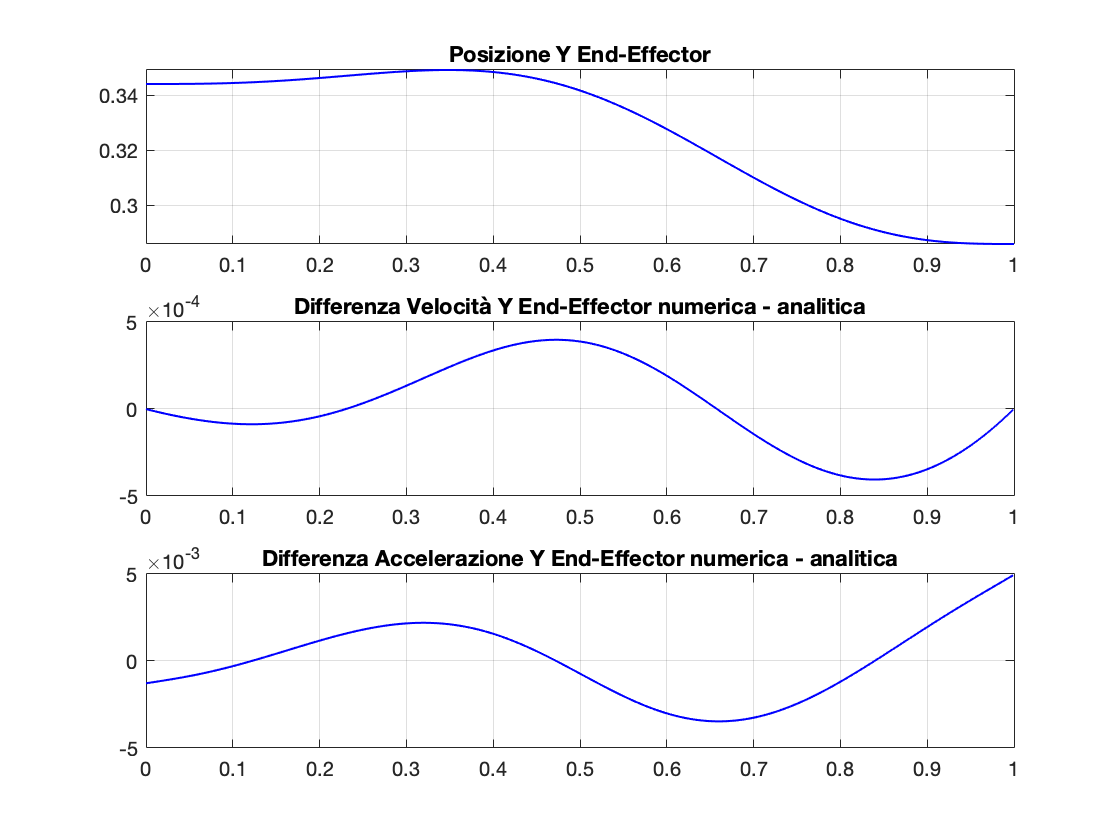

Plot_EF(PKM,P, P_p34, P_pp34, P_pM)

**Confronto cinematica matlab e adams**

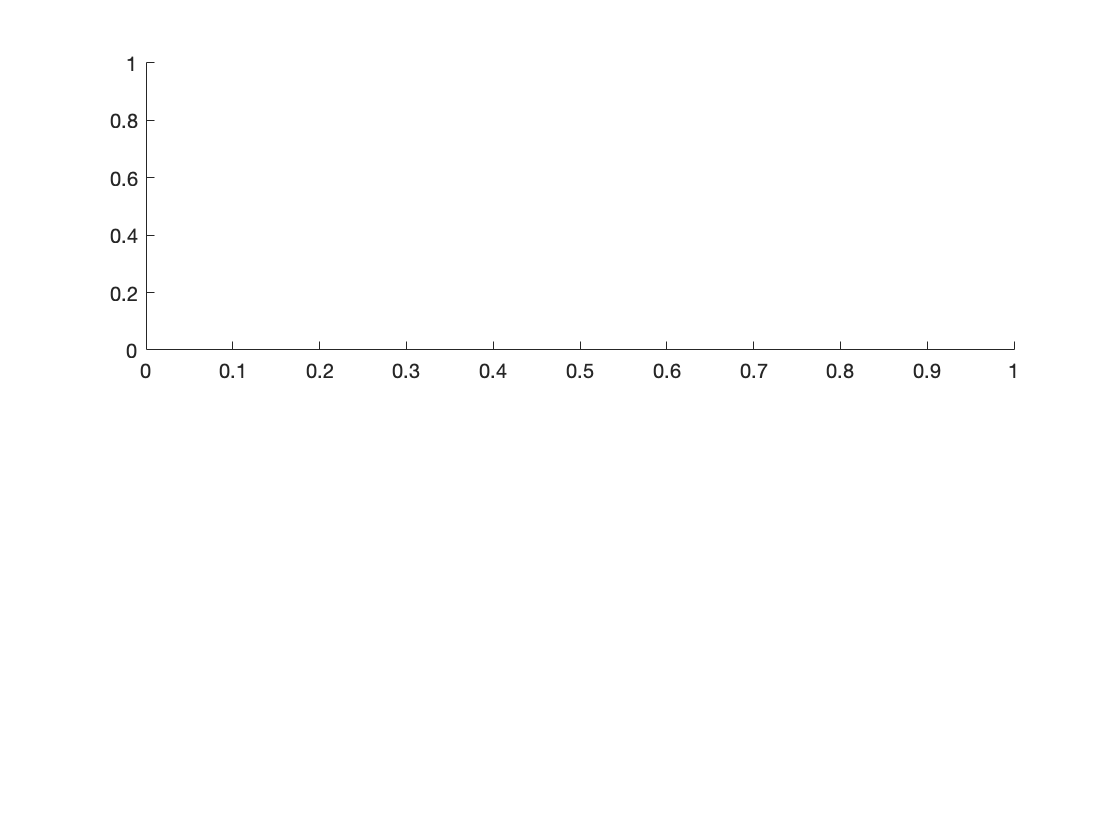

load PKM_PosEF
load PKM_VelEF
load PKM_AccEF
load PKM_PosE1
load PKM_VelE1
load PKM_AccE1
load PKM_Pa_VelCM
time = linspace(0,PKM.ta,length(Theta_p));
C1x_p_ad = PKM_Pa_VelCM(:,1);
C1x_p_ad = C1x_p_ad';
C1y_p_ad = PKM_Pa_VelCM(:,2);
C1y_p_ad = C1y_p_ad';
figure
subplot(2,1,1);

%plot(time,C2_p(1,:)-C1x_p_ad,'color','b','linewidth',1)
% title('Errore velocità X C1 Matlab-Adams')
% grid on
% 
% subplot(2,1,2); 
% plot(time,C2_p(2,:)-C1y_p_ad,'color','b','linewidth',1)
% title('Errore velocità Y C1 Matlab-Adams')
% grid on
% Matlab_Adams_Cinematica(PKM_PosEF, P, PKM_VelEF, P_p, PKM_AccEF, P_pp, PKM_PosE1, E1, PKM_VelE1, E1_p, PKM_AccE1, E1_pp)

## Cinematica Inversa

**Analisi di posizione**

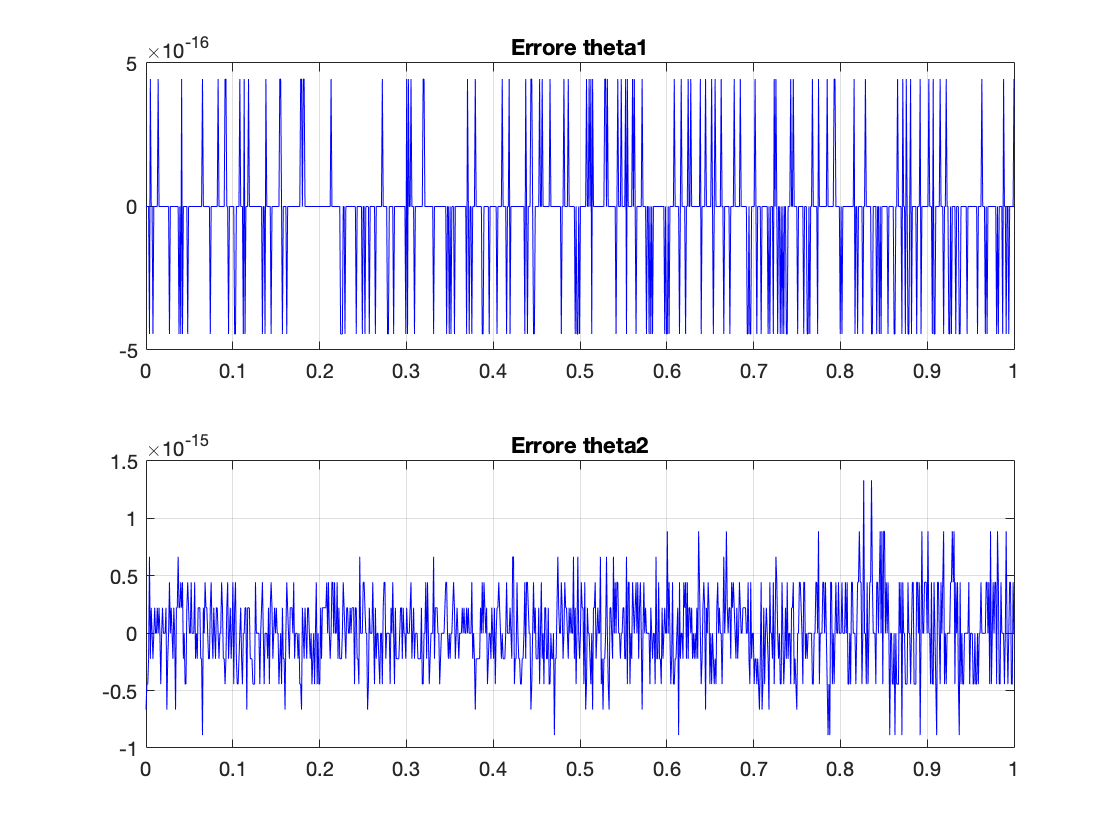

[theta1inv,theta2inv] = Cinematica_Inversa_Posizione(P, PKM, theta1ldm, theta2ldm);
Errore_theta1 = theta1ldm - theta1inv;
Errore_theta2 = theta2ldm - theta2inv;
time = linspace(0,PKM.ta,length(Theta_p));

figure
subplot(2,1,1);
plot(time,Errore_theta1,'color','b')
title('Errore theta1')
grid on
subplot(2,1,2); 
plot(time,Errore_theta2,'color','b')
title('Errore theta2')
grid on

**Rappresentazione grafica**

%animation(PKM.link.d, PKM.link.l,theta1inv,theta2inv,theta3,theta4)

**Analisi di velocità**

Theta_p_inv = Cinematica_Inversa_Velocita(J,P_p);

**Analisi di accelerazione**

% Theta_pp_inv = Cinematica_Inversa_Accelerazione(J_p,J,Theta_p,P_pp);

## Dinamica

**Metodo azioni vicolari**

[C1_AV, C2_AV] = Dinamica(PKM,theta1ldm,theta2ldm,theta3,theta4,theta1ldm_p,theta2ldm_p,theta3_p,theta4_p,...
    theta1ldm_pp,theta2ldm_pp,theta3_pp,theta4_pp,thetavldm_pp)

C1_AV =          0    0.0157    0.0314    0.0469    0.0624    0.0777    0.0930    0.1082    0.1232    0.1382    0.1531    0.1679    0.1826    0.1972    0.2117    0.2262    0.2405    0.2547    0.2689    0.2830    0.2969    0.3108    0.3246    0.3383    0.3519    0.3655    0.3789    0.3922    0.4055    0.4187    0.4317    0.4447    0.4577    0.4705    0.4832    0.4958    0.5084    0.5209    0.5333    0.5456    0.5578    0.5699    0.5820    0.5939    0.6058    0.6176    0.6293    0.6410    0.6525    0.6640


C2_AV =          0    0.0220    0.0439    0.0656    0.0872    0.1087    0.1300    0.1512    0.1723    0.1932    0.2140    0.2347    0.2553    0.2757    0.2960    0.3162    0.3362    0.3561    0.3759    0.3955    0.4151    0.4345    0.4537    0.4729    0.4919    0.5108    0.5296    0.5482    0.5667    0.5851    0.6033    0.6215    0.6395    0.6574    0.6751    0.6928    0.7103    0.7277    0.7449    0.7621    0.7791    0.7960    0.8127    0.8294    0.8459    0.8623    0.8786    0.8948    0.9108    0.9267


**Metodo PLV**

[C1_PLV, C2_PLV, M, K] = Dinamica_PLV(PKM,theta1ldm_p,theta2ldm_p,theta1ldm_pp,theta2ldm_pp,J1,J2,J3,J4,JE,J34,J1p,J2p,J3p,J4p,JEp,J34p)

C1_PLV =          0    0.0151    0.0301    0.0450    0.0598    0.0745    0.0892    0.1037    0.1182    0.1325    0.1468    0.1610    0.1751    0.1891    0.2030    0.2168    0.2306    0.2442    0.2578    0.2713    0.2847    0.2980    0.3112    0.3244    0.3374    0.3504    0.3633    0.3761    0.3888    0.4014    0.4139    0.4264    0.4388    0.4511    0.4633    0.4754    0.4874    0.4994    0.5113    0.5231    0.5348    0.5464    0.5580    0.5694    0.5808    0.5921    0.6033    0.6145    0.6256    0.6365


C2_PLV =          0    0.0209    0.0417    0.0623    0.0828    0.1032    0.1235    0.1436    0.1637    0.1836    0.2033    0.2230    0.2425    0.2619    0.2812    0.3004    0.3194    0.3383    0.3571    0.3758    0.3943    0.4127    0.4310    0.4492    0.4673    0.4852    0.5031    0.5208    0.5384    0.5558    0.5732    0.5904    0.6075    0.6245    0.6414    0.6581    0.6748    0.6913    0.7077    0.7240    0.7401    0.7562    0.7721    0.7879    0.8036    0.8192    0.8347    0.8500    0.8653    0.8804


M =     0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215
   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0.4345   -0.1215    0

K =          0         0   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0000    0.0001   -0.0000    0.0002   -0.0001    0.0002   -0.0001    0.0003   -0.0001    0.0004   -0.0001    0.0005   -0.0001    0.0006   -0.0002    0.0007   -0.0002    0.0008   -0.0002    0.0009   -0.0003    0.0011   -0.0003    0.0012   -0.0003    0.0014   -0.0004    0.0015   -0.0004    0.0017   -0.0005    0.0019   -0.0005    0.0021   -0.0006    0.0023   -0.0006    0.0025   -0.0007    0.0027
         0         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0001   -0.0002   -0.0001   -0.0003   -0.0002   -0.0003   -0.0002   -0.0004   -0.0002   -0.0004   -0.0003   -0.0005   -0.0003   -0.0005   -0.0003   -0.0006   -0.0004   -0.0006   -0.0004   -0.0007   -0.0005   -0.0008   -0.0005   -0.0009   -0.0006   -0.0009   -0.0006   -0.0010   -0

**Confronto tra i due metodi**

%ErrC1 = C1_PLV(1,:)-C1_AV(1,:);
% ErrC2 = C2_PLV(1,:)-C2_AV(1,:);
% figure
% subplot(2,1,1);
% plot(time(1,:),C1_PLV(1,:),'color','b','linewidth',1)
% title('Coppia theta1 PLV')
% grid on
% subplot(2,1,2);
% plot(time(1,:),C2_PLV(1,:),'color','k','linewidth',1)
% title('Coppia theta2 PLV')
% grid on

**Confronto dinamica Matlab-Adams**

% load PKM_Pa_CoppieNOEF
% Matlab_Adams_Dinamica(PKM_Pa_CoppieNOEF, -C1_PLV, -C2_PLV)

**Dinamica inversa calcolo Coppie**

Condizioni = [theta1ldm(1,1),theta2ldm(1,1),theta1ldm_p(1,1),theta2ldm_p(1,1)]

Condizioni =     2.0944    1.0472         0         0


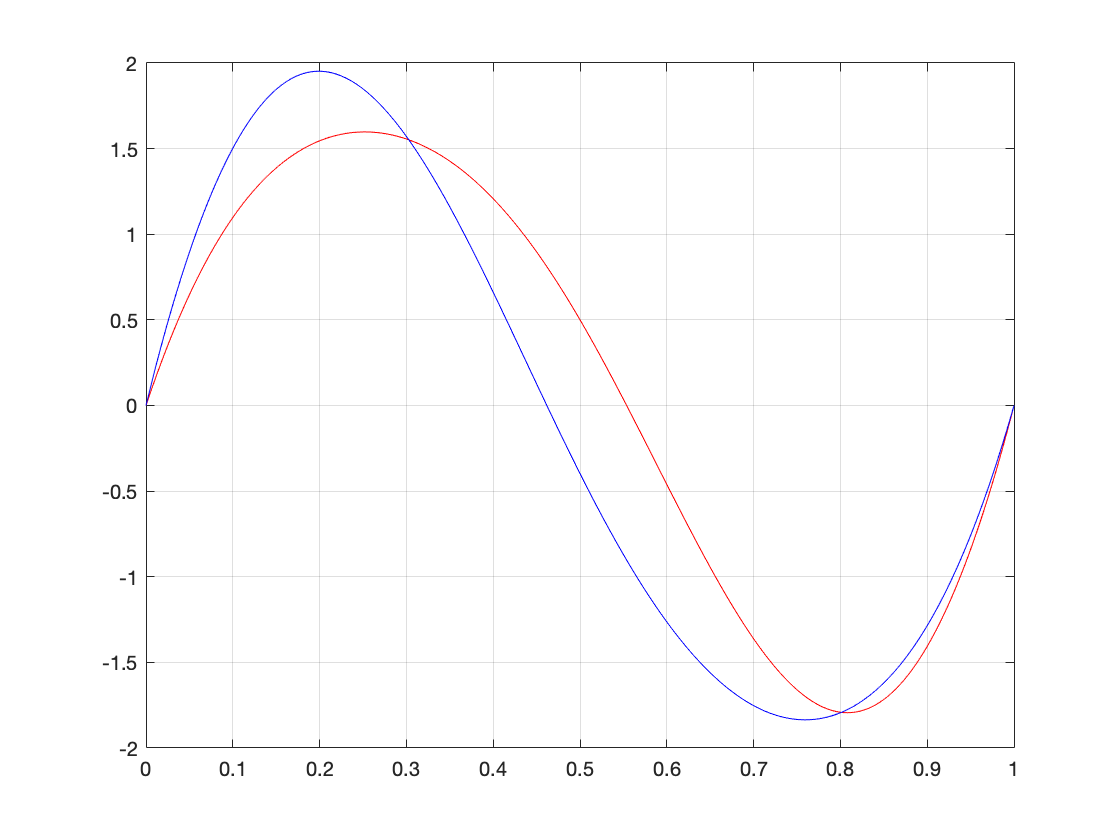

[ThetaInt,Theta_pInt,Theta_ppInt] =  DinamicaInversa([C1_PLV;C2_PLV],Condizioni);
figure
plot(linspace(0,1,1000),C1_PLV,"Color","red")
hold on 
grid on
plot(linspace(0,1,1000),C2_PLV,"Color","b")

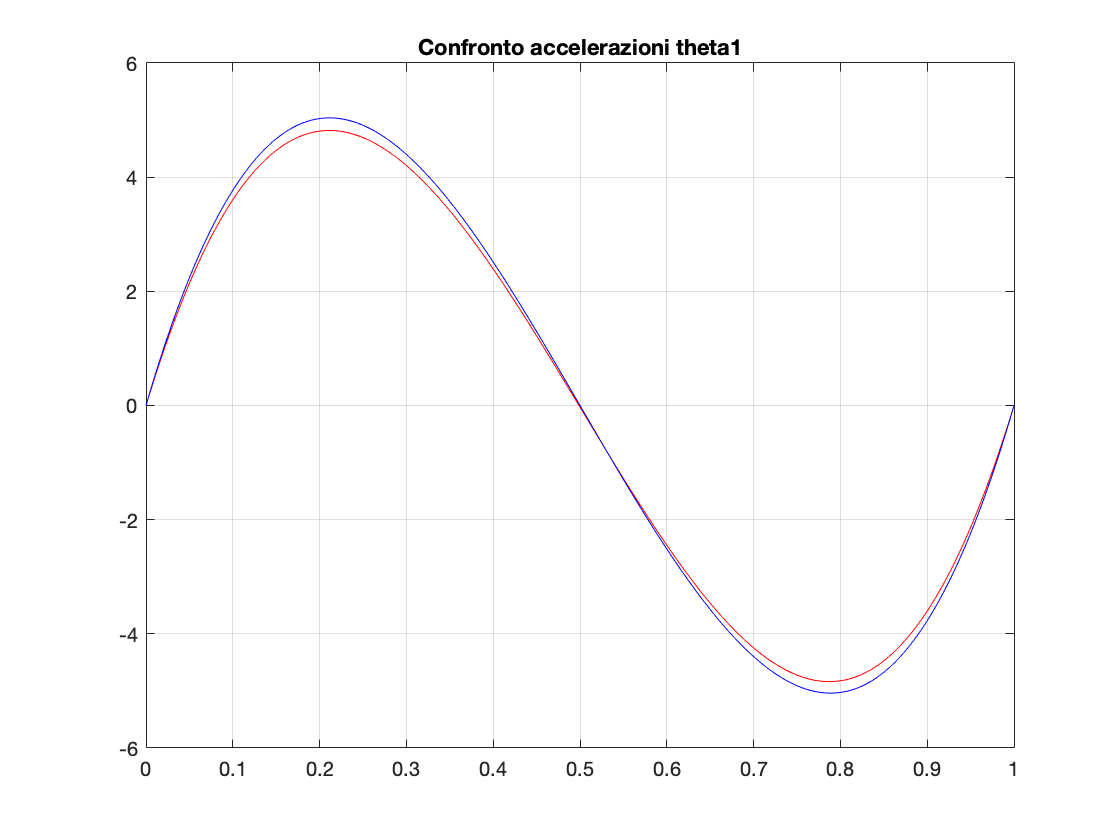

figure
plot(linspace(0,1,1000),Theta_ppInt(1,:),"Color","red")
hold on
grid on
plot(linspace(0,1,1000),theta1ldm_pp(1,:),"Color","b")
title('Confronto accelerazioni theta1')

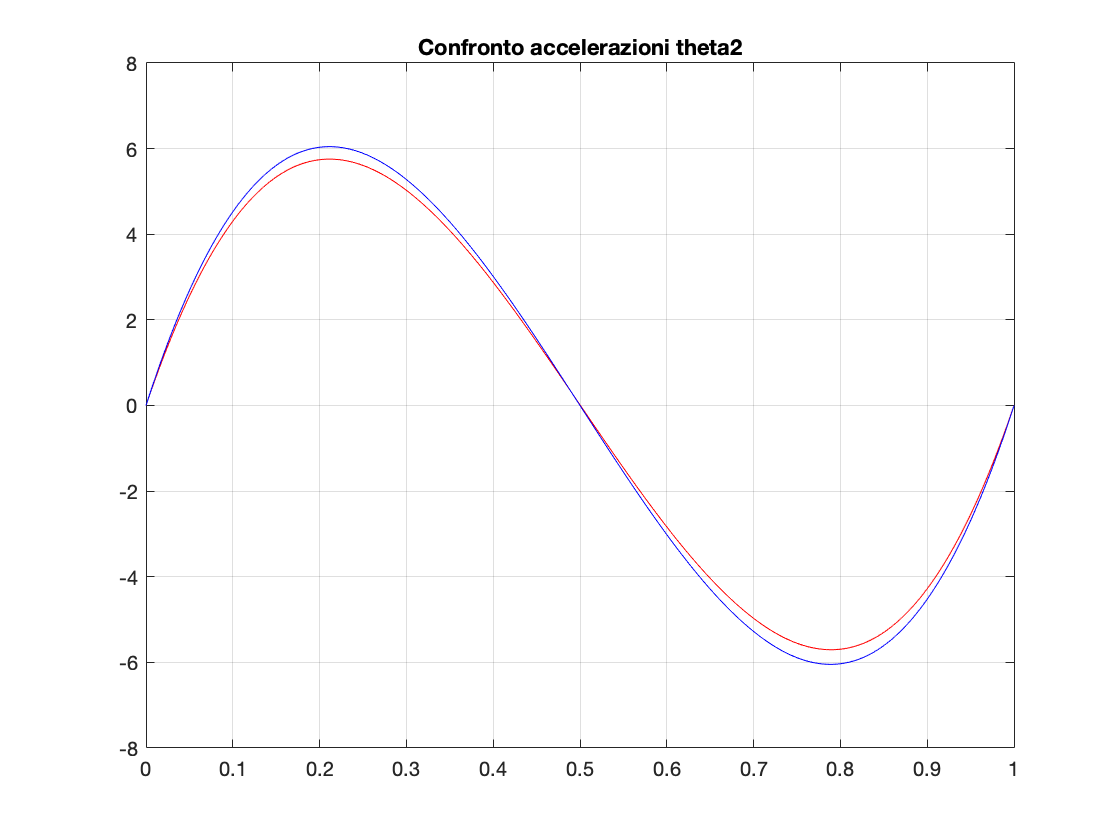

figure
plot(linspace(0,1,1000),Theta_ppInt(2,:),"Color","red")
hold on
grid on
plot(linspace(0,1,1000),theta2ldm_pp(1,:),"Color","b")
title('Confronto accelerazioni theta2')

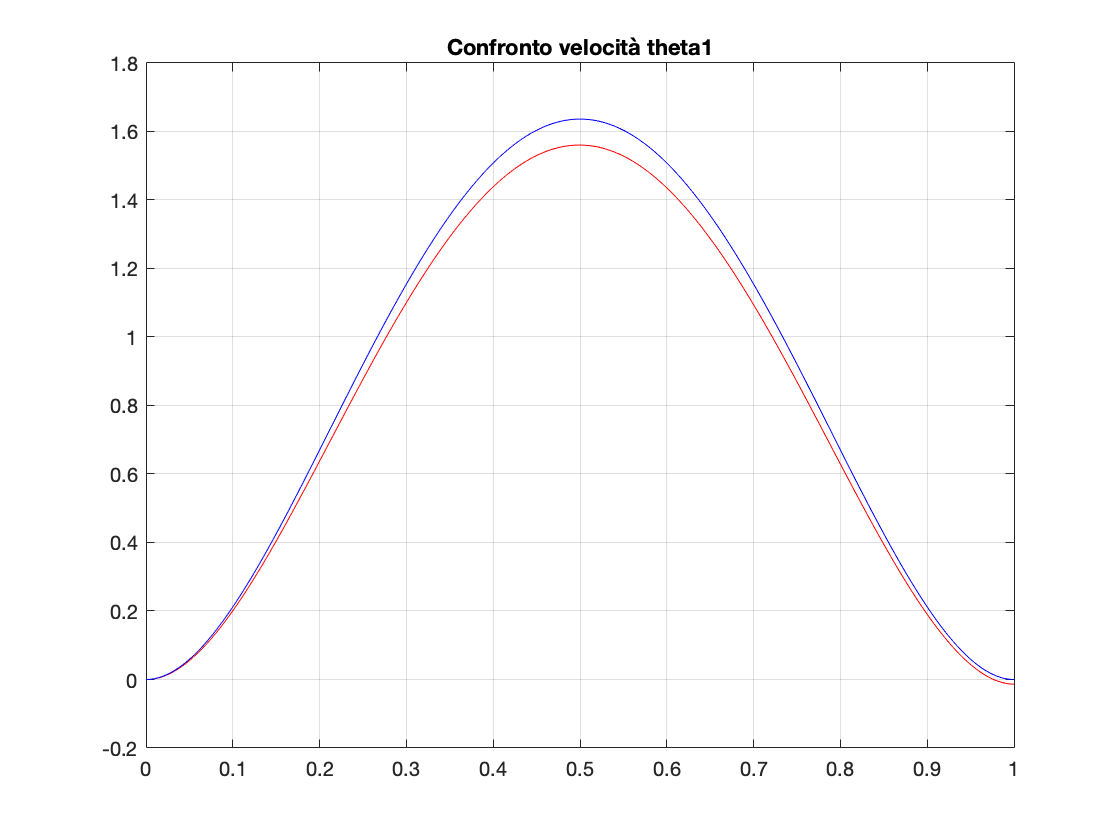

figure
plot(linspace(0,1,1000),Theta_pInt(1,:),"Color","red")
hold on
grid on
plot(linspace(0,1,1000),theta1ldm_p(1,:),"Color","b")
title('Confronto velocità theta1')

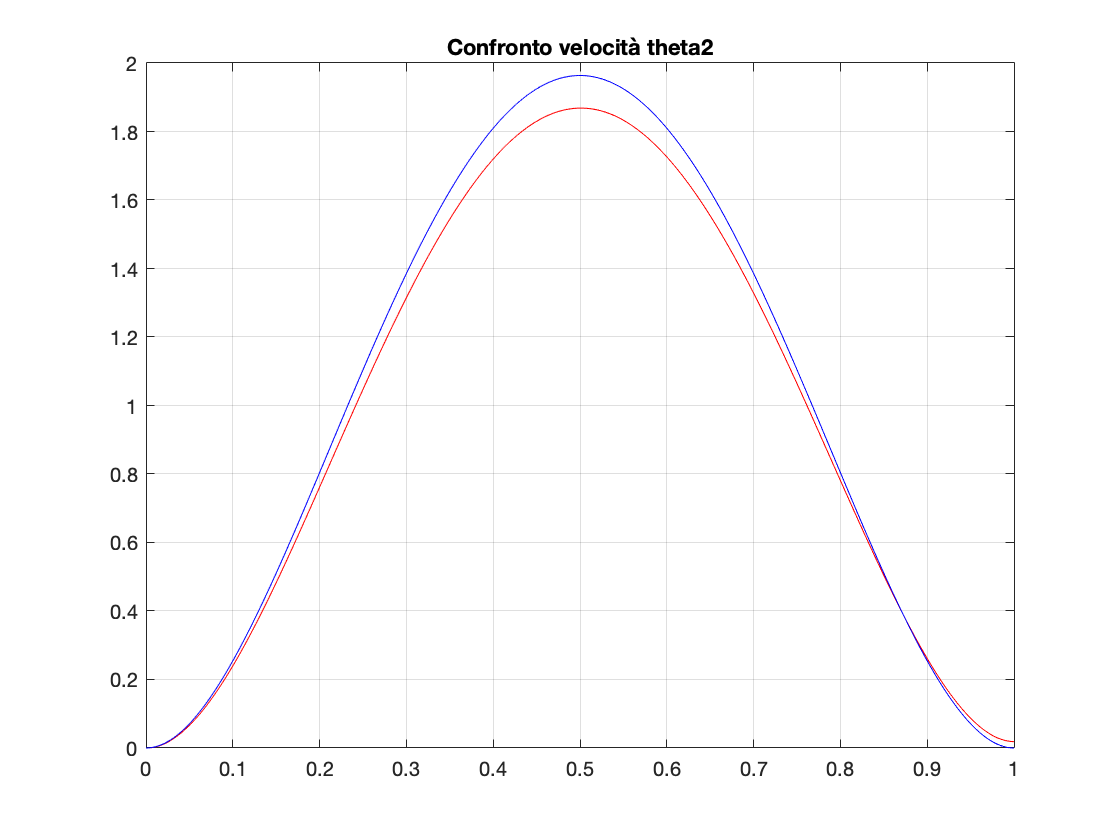

figure
plot(linspace(0,1,1000),Theta_pInt(2,:),"Color","red")
hold on
grid on
plot(linspace(0,1,1000),theta2ldm_p(1,:),"Color","b")
title('Confronto velocità theta2')

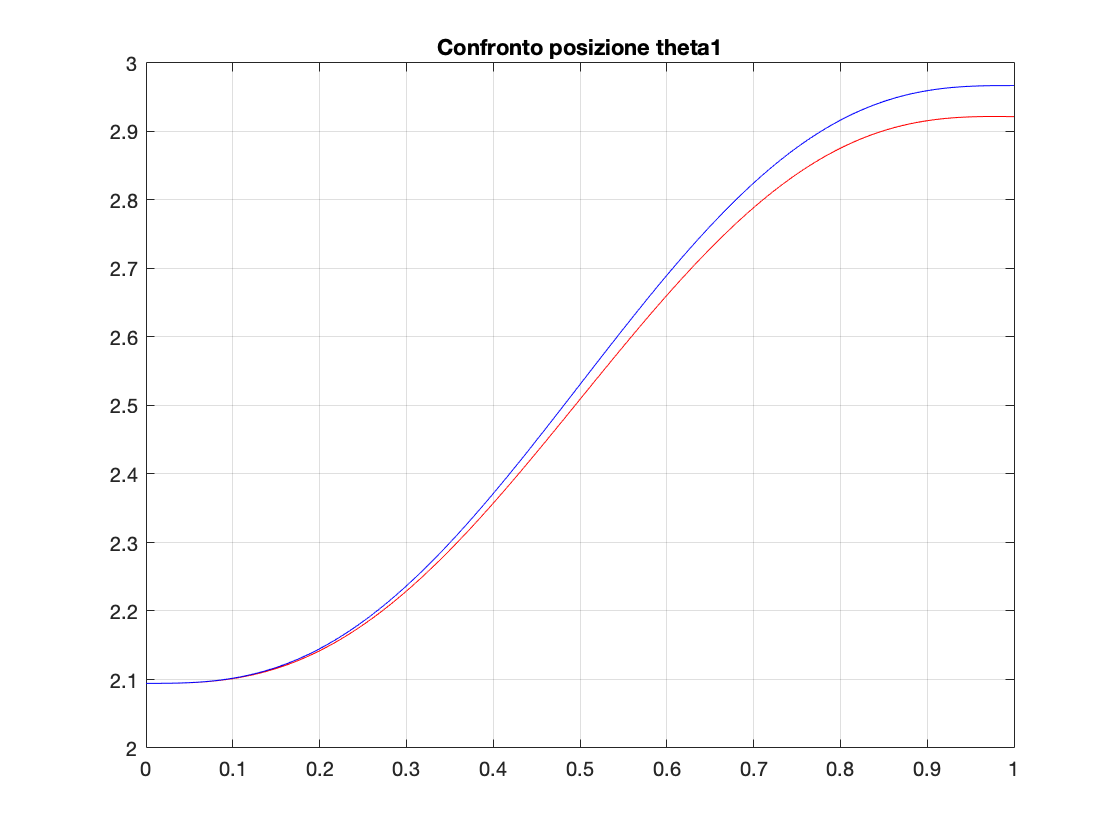


figure
plot(linspace(0,1,1000),ThetaInt(1,:),"Color","red")
hold on
grid on
plot(linspace(0,1,1000),theta1ldm(1,:),"Color","b")
title('Confronto posizione theta1')

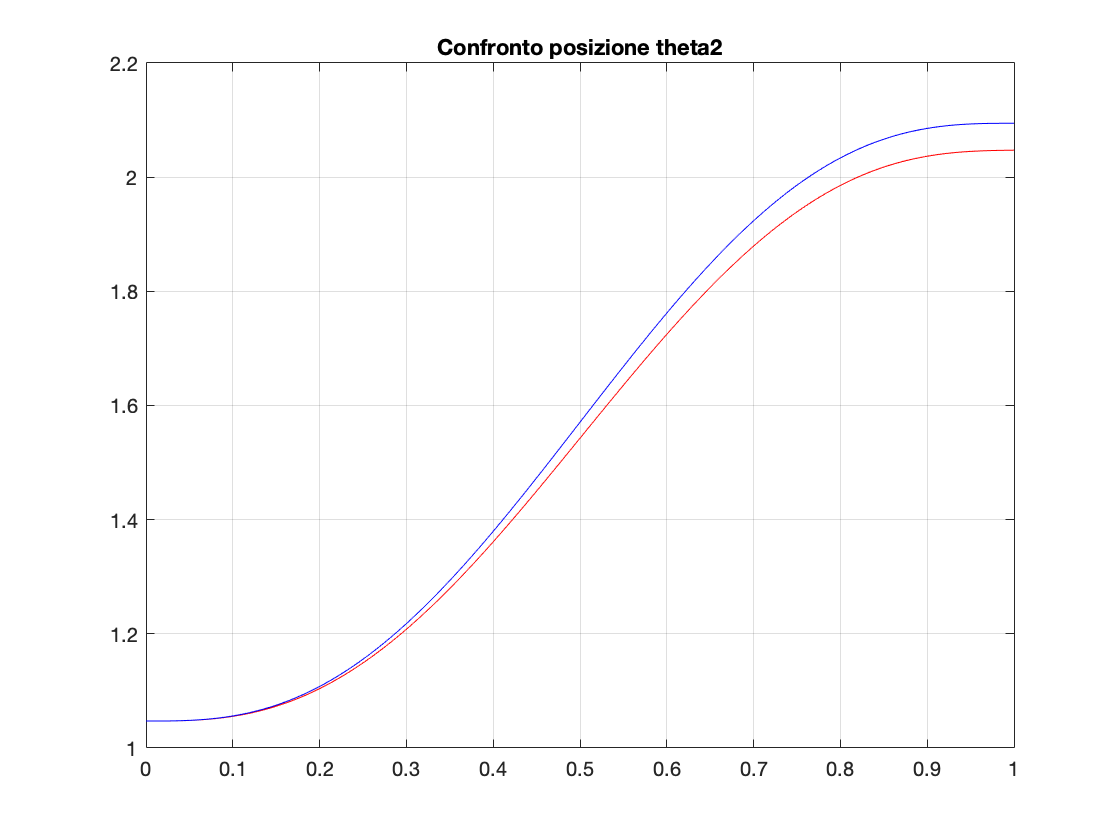

figure
plot(linspace(0,1,1000),ThetaInt(2,:),"Color","red")
hold on
grid on
plot(linspace(0,1,1000),theta2ldm(1,:),"Color","b")
title('Confronto posizione theta2')